#  **TP4 : Filtre de Kalman**

##  2- Applications

####  2.1 Estimation du niveau de l'eau dans un réservoir

clc; 
clear all;

load('reservoir1.mat','y');

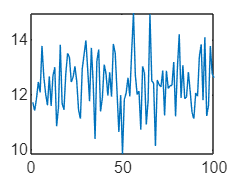

plot (y);

#### Boucle pour tester différentes configurations

N = length(y); % Nombre de mesures

% Paramètres du modèle
A = 1; % Modèle d'état (niveau constant)
C = 1; % Observation directe
Qb = 0.5; % Bruit de processus (faible)

% Paramètres à tester
Qv_values = [0.1, 0.5, 1]; % Différents choix pour la covariance du bruit de mesure
P1_values = [0.1, 1, 10];  % Différents choix pour l'estimation initiale de P1
% Qv_values = 0.1
% P1_values = 0.1

% Boucles pour tester différents paramètres
results = cell(length(Qv_values), length(P1_values));

for i = 1:length(Qv_values)
    for j = 1:length(P1_values)
        Qv = Qv_values(i);
        P_current = P1_values(j); % Estimation initiale de la covariance
        G_current = 0; % Initialisation du gain de Kalman
        
        % Initialisation des prédictions
        x_current_pred = 0; % Estimation initiale
        x_est = zeros(1, N); % Stockage des estimations
        P_est = zeros(1, N); % Stockage des covariances
        
        % Boucle pour les étapes Kalman
        for n = 1:N
            % Mise à jour des paramètres avec update_filter
            [G_next, P_next_pred] = update_filter(G_current, P_current, A, Qb, C, Qv);
            
            % Mise à jour de la prédiction avec predict
            x_next_pred = predict(x_current_pred, y(n), G_current, A, 0, C);
            
            % Stockage des résultats
            x_est(n) = x_next_pred;
            P_est(n) = P_next_pred;
            
            % Préparation pour l'itération suivante
            G_current = G_next;
            P_current = P_next_pred;
            x_current_pred = x_next_pred;
        end
        
        % Sauvegarder les résultats
        results{i, j} = struct('x_est', x_est, 'P_est', P_est, 'Qv', Qv, 'P1', P1_values(j));
    end
end


#### Tracer les résultats

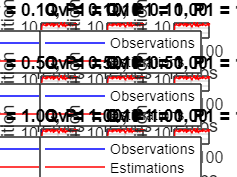

figure;
for i = 1:length(Qv_values)
    for j = 1:length(P1_values)
        subplot(length(Qv_values), length(P1_values), (i-1)*length(P1_values) + j);
        plot(1:N, y, 'b', 'DisplayName', 'Observations');
        hold on;
        plot(1:N, results{i, j}.x_est, 'r', 'DisplayName', 'Estimations');
        xlabel('Temps');
        ylabel('Position');
        title(sprintf('Qv = %.2f, P1 = %.2f', Qv_values(i), P1_values(j)));
        legend;
        grid on;
    end
end

#### Tracer la convergence de la variance

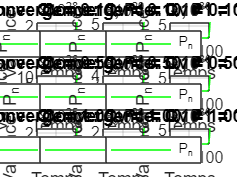

figure;
for i = 1:length(Qv_values)
    for j = 1:length(P1_values)
        subplot(length(Qv_values), length(P1_values), (i-1)*length(P1_values) + j);
        plot(1:N, results{i, j}.P_est, 'g', 'DisplayName', 'P_n');
        xlabel('Temps');
        ylabel('Variance P_n');
        title(sprintf('Convergence: Qv = %.2f, P1 = %.2f', Qv_values(i), P1_values(j)));
        legend;
        grid on;
    end
end

% Charger les données
load('reservoir2.mat'); % Charge la variable y (observations)
N = length(y); % Nombre de mesures

% Paramètres du modèle
dt = 1; % Intervalle de temps entre deux observations
A = [1, dt; 0, 1]; % Matrice de transition (niveau et vitesse)
C = [1, 0]; % Matrice d'observation (seule la position est observée)
Qb = [0.01, 0; 0, 0.01]; % Bruit de processus (faible pour niveau et vitesse)
Qv = 0.5; % Bruit de mesure

% Initialisation
x_current_pred = [0; 0]; % Estimation initiale : [niveau, vitesse]
P_current = eye(2) * 10; % Covariance initiale large pour refléter l'incertitude
x_est = zeros(2, N); % Stockage des estimations : [niveau; vitesse]
P_est = zeros(2, 2, N); % Stockage des covariances

% Boucle Kalman
for n = 1:N
    % Mise à jour avec l'observation
    % Calcul du gain de Kalman et de la covariance prédite
    [G_current, P_current] = update_filter(G_current, P_current, A, Qb, C, Qv);
                             
    % Mise à jour de la prédiction avec l'observation actuelle
    x_next_pred = predict(x_current_pred, y(n), G_current, A, [0; 0], C);
    
    % Stockage des résultats
    x_est(:, n) = x_next_pred;
    P_est(:, :, n) = P_current;
    
    % Préparation pour l'itération suivante
    x_current_pred = x_next_pred;
end

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in update_filter (line 25)
    G_pred = - P_pred_next * C / (C' * P_pred_next * C + Qv);

Related documentation


% Tracer les résultats
figure;
subplot(2, 1, 1);
plot(1:N, y, 'b', 'DisplayName', 'Observations');
hold on;
plot(1:N, x_est(1, :), 'r', 'DisplayName', 'Estimation du niveau');
xlabel('Temps');
ylabel('Niveau d\eau');
title('Estimation du niveau d\eau');
legend;
grid on;

subplot(2, 1, 2);
plot(1:N, x_est(2, :), 'g', 'DisplayName', 'Estimation de la vitesse');
xlabel('Temps');
ylabel('Vitesse de remplissage');
title('Estimation de la vitesse de remplissage');
legend;
grid on;

% Convergence de la covariance
P_convergence = squeeze(P_est(1, 1, :)); % Extraction de la variance du niveau
figure;
plot(1:N, P_convergence, 'm', 'DisplayName', 'Variance P_{h}');
xlabel('Temps');
ylabel('Variance');
title('Convergence de la variance du niveau');
grid on;
